Call the ROC script

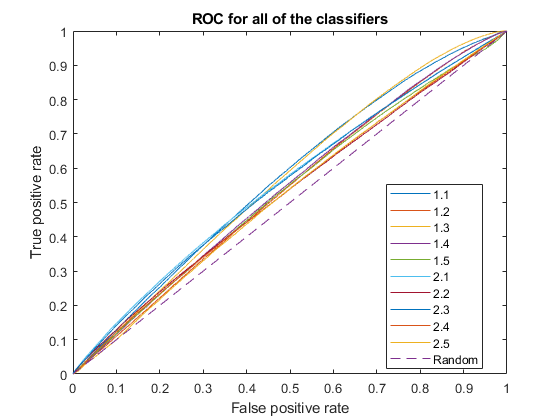

AUC11 =    5.6975e-01


AUC12 =    5.3699e-01


AUC13 =    5.6711e-01


AUC14 =    5.4222e-01


AUC15 =    5.3355e-01


AUC21 =    5.5777e-01


AUC22 =    5.2921e-01


AUC23 =    5.5458e-01


AUC24 =    5.2885e-01


AUC25 =    5.2410e-01


roc_v9_second_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    if ((i>1 && i<5) || (i>6 && i<10))
        continue;
    end
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans =    9.6333e-01


ans =    153


ans =    9.1977e-01


ans =    8.9844e-02


ans =    9.1977e-01


ans =    7.6716e-01


ans =    8.5820e-01


Classifier 2

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 3

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 4

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 5

ans =    9.7072e-01


ans =    119


ans =    7.4458e-01


ans =    2.3640e-01


ans =    7.4458e-01


ans =    6.0403e-01


ans =    6.5777e-01


Classifier 6

ans =    2.6402e-02


ans =     74


ans =    8.5143e-01


ans =    1.4748e-01


ans =    8.5143e-01


ans =    3.4659e-01


ans =    4.3286e-01


Classifier 7

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 8

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 9

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 10

ans =    1.4920e-06


ans =    105


ans =    6.8779e-01


ans =    3.0229e-01


ans =    6.8779e-01


ans =    5.3725e-01


ans =    5.7844e-01


Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val =    9.1977e-01


ind =      1


Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom =    7.7955e-01


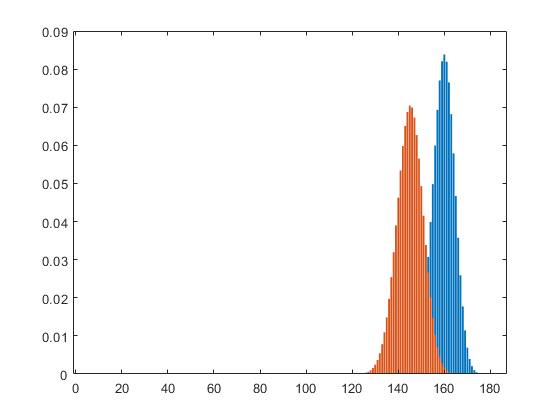

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Save results

save('./results_characterization/v9_second_op_2.mat','selectedPoints');